# **Taylor Differentiation Method Code**

## Input

clear;clc
n=100;      % numer of iteration
a=1;        %interval start value
b=5;        %interval end value
h=(b-a)/n;   % step size


## x discretization

x=a:h:b; 
y=zeros(size(x));

## Intial condition

y(1)=1; 

## Differential Eq. y'=f(x,y)=e^(2x)+ln(x)

% The loop to solve the DE
fprintf(" n      x        y");

 n      x        y

fprintf('%2i %9.5f %9.5f',0, a,y(1));

 0   1.00000   1.00000

for i=1:n
    % adding precion with 1st and 2nd derivatif
    f1 = exp(2 * x(i)) + log(x(i)); % function
    f2 = 2 * exp(2 * x(i)) + 1 / x(i); % 1st derivatif
    f3 = 4 * exp(2 * x(i)) - 1 / (x(i)^2); %second derivatif
    y(i+1) = y(i) + h * f1 + ((h^2)/factorial(2)) * f2 + ((h^3)/factorial(3)) * f3; % y_n-1
    fprintf('%2i %9.5f %9.5f\n',i, x(i+1),y(i+1));
end

 1   1.04000   1.30849
 2   1.08000   1.64414
 3   1.12000   2.00904
 4   1.16000   2.40545
 5   1.20000   2.83581
 6   1.24000   3.30279
 7   1.28000   3.80930
 8   1.32000   4.35848
 9   1.36000   4.95373
10   1.40000   5.59876
11   1.44000   6.29758
12   1.48000   7.05455
13   1.52000   7.87439
14   1.56000   8.76221
15   1.60000   9.72356
16   1.64000  10.76446
17   1.68000  11.89142
18   1.72000  13.11150
19   1.76000  14.43236
20   1.80000  15.86230
21   1.84000  17.41030
22   1.88000  19.08610
23   1.92000  20.90026
24   1.96000  22.86422
25   2.00000  24.99035
26   2.04000  27.29208
27   2.08000  29.78397
28   2.12000  32.48175
29   2.16000  35.40251
30   2.20000  38.56474
31   2.24000  41.98847
32   2.28000  45.69541
33   2.32000  49.70908
34   2.36000  54.05495
35   2.40000  58.76062
36   2.44000  63.85598
37   2.48000  69.37344
38   2.52000  75.34808
39   2.56000  81.81791
40   2.60000  88.82411
41   2.64000  96.41130
42   2.68000 104.62779
43   2.72000 113.52596
44   2.7600

## Visualization

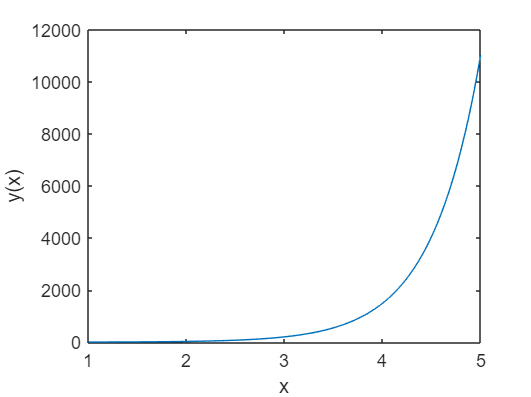

figure(1)
plot(x,y)
xlabel('x')
ylabel('y(x)')